V = VideoReader("..\data\240828_AUZ0752_OD_HD_0\avi\240828_AUZ0752_OD_HD_0_M0.avi");
video = zeros(V.Height, V.Width, V.NumFrames,'single');
[Ny,Nx,Nt] = size(video);
for n = 1:V.NumFrames
    video(:, :, n) = rgb2gray(read(V, n));
end

clear V

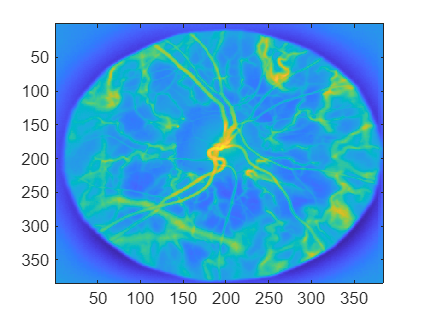


meanImg = mean(video,3);
imagesc(meanImg);

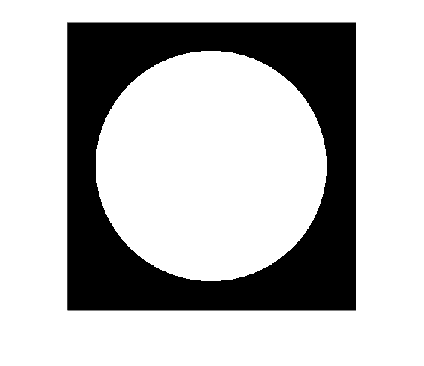

[x, y] = meshgrid(1:Ny, 1:Nx);
diaphragm = sqrt((x - Nx/2) .^ 2 + (y - Ny/2) .^ 2) <= 0.4 * (Ny + Nx) / 2;
imshow(diaphragm);

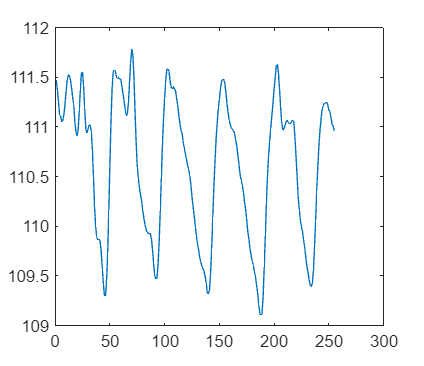

pulse = (sum(video.*diaphragm,[1,2])/nnz(diaphragm));
plot(squeeze(pulse));

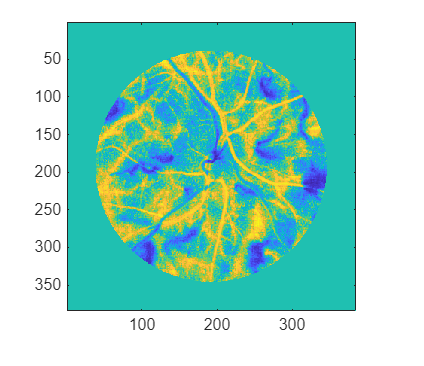

cor = mean((video-meanImg).*diaphragm .* (pulse-mean(pulse,3)),3)./(std((video-meanImg),[],3)*std(pulse-mean(pulse,3),[],3));
imagesc(cor);

threshold = 0.595;
num_parts = 6

num_parts = 6

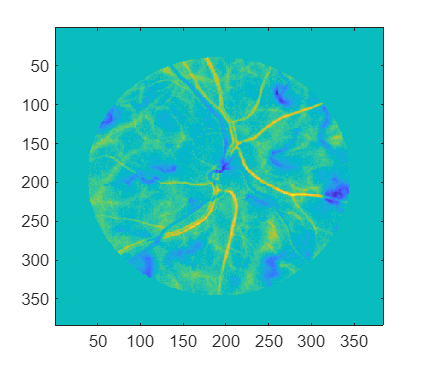

imshow(bwareafilt(cor>threshold,num_parts));

video_flat = reshape(video.*diaphragm,[Nx*Ny,Nt]);
if true
    video_flat = normalize(video_flat,2);
end
video_flat(~reshape(diaphragm,[1 Nx*Ny]))=NaN;
[idx,C,~,~] = kmeans(video_flat,6,'Distance',"correlation",'MaxIter',2000);

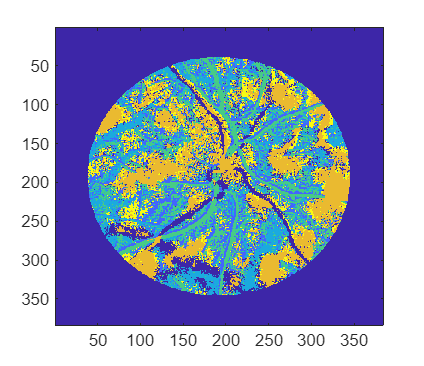

idx = reshape(idx,[Nx,Ny]);

imagesc(idx);

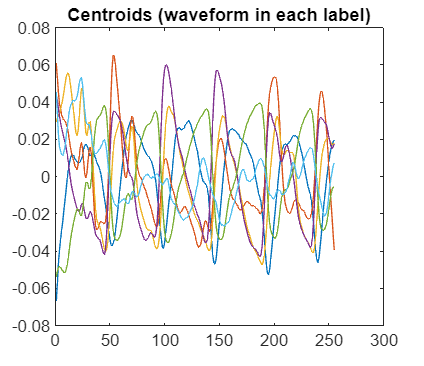

m=0;
idxArtery = 0;
for c = 1:size(C,1)
    plot(C(c,:));
    hold on
    if sum(cor.*(idx==c),[1,2])>m
        m=sum(cor.*(idx==c),[1,2]);
        idxArtery = c;
    end
end
title('Centroids (waveform in each label)')
hold off

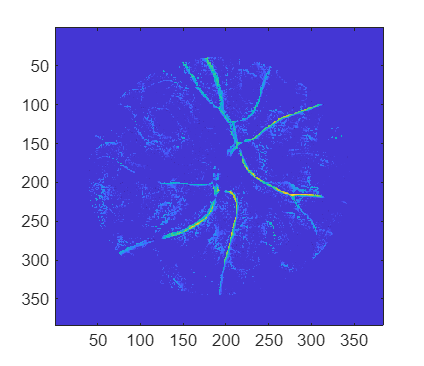

imagesc(cor.*(idx==idxArtery))

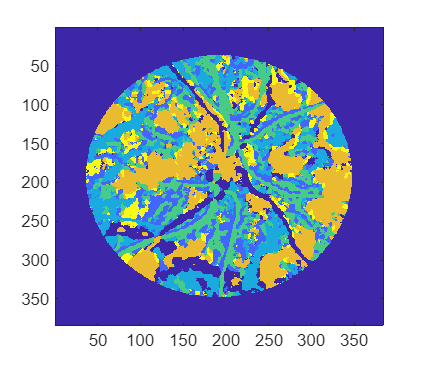

L = idx;
[x, y] = meshgrid(1:Ny, 1:Nx);
positions = cat(3,x,y);
positions = reshape(positions,Nx*Ny,[]);
%positions(~reshape(diaphragm,[1 Nx*Ny]),:)=[];
nn_indicies = knnsearch(positions,positions,Distance='euclidean',K=19);
new_L = mode(L(nn_indicies),2);
new_L = reshape(new_L,Nx,Ny);
imagesc(new_L)

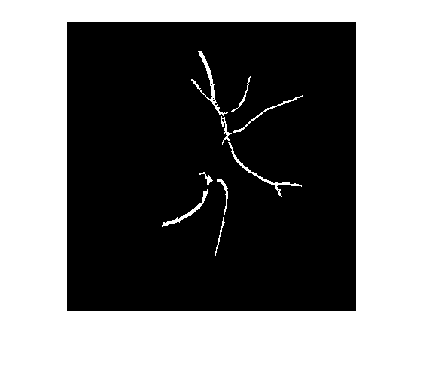

mask=bwareafilt(cor>0.29&bwareafilt((new_L==idxArtery),8),7);
imshow(mask)